# Acquire Data

## Discover Analog input

devices = daq.getDevices();
dev = devices.ID;
s = daq.createSession('ni');
addAnalogInputChannel(s, dev, 'ai0', 'voltage');



s.Rate = 100000

s = Data acquisition session using National Instruments hardware:
   Will run for 1000 scans (0.01 seconds) at 100000 scans/second.
   Number of channels: 1
      index Type Device Channel MeasurementType      Range       Name
      ----- ---- ------ ------- --------------- ---------------- ----
      1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
   
Properties, Methods, Events


s.NumberOfScans = 1000

s = Data acquisition session using National Instruments hardware:
   Will run for 1000 scans (0.01 seconds) at 100000 scans/second.
   Number of channels: 1
      index Type Device Channel MeasurementType      Range       Name
      ----- ---- ------ ------- --------------- ---------------- ----
      1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
   
Properties, Methods, Events


data = s.inputSingleScan % gets just a point for each input

data = -0.0800

[data, time] = s.startForeground;

## Plot data

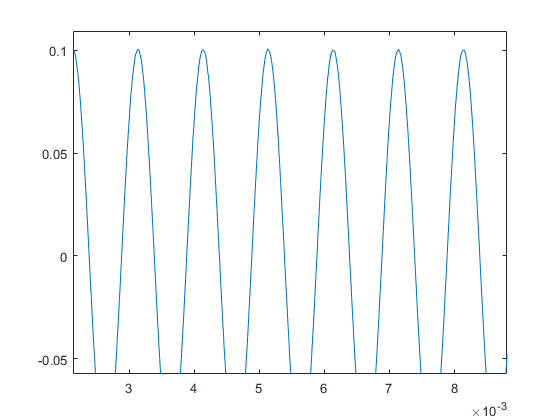

plot(time, data)